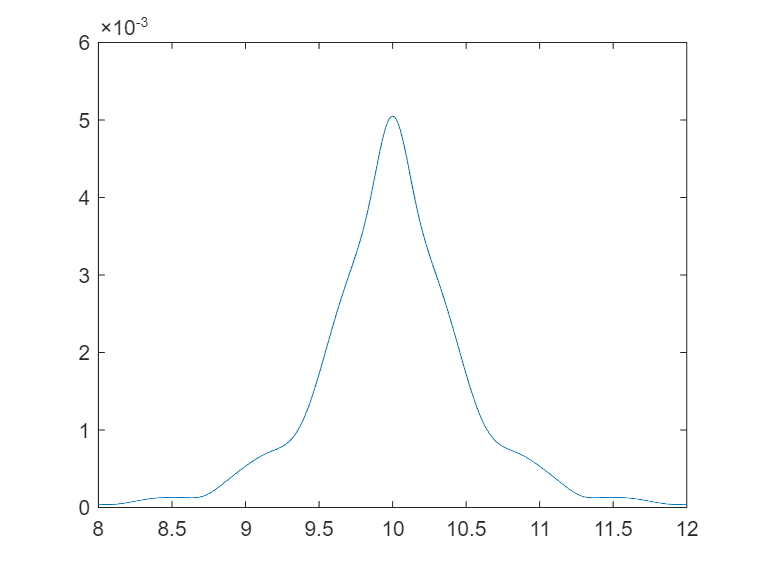

clear all
clc
nPoint = 2^23;
z0 = 10;
sigma = 0:0.0083:(nPoint-1)*0.0083;
fSigma = fitfSigma(sigma);
pSigma = -4*pi*z0*sigma;
iSigma = fSigma.*exp(1i*pSigma);

deltaSigma = (sigma(end)-sigma(1))/(nPoint-1);
deltaZ = 1/(2*nPoint*deltaSigma);
zData = (1:nPoint)*deltaZ;
ifftIsigma = ifft(iSigma);
intensity = abs(ifftIsigma);
phase0 = angle(ifftIsigma);


%unwrap phase,from z=9 to z=11.
unwrapZ1 = zData(abs(zData-10)<0.001);
unwrapZend = zData(abs(zData-16)<0.001);
unwrapZ_1 = zData(abs(zData-4)<0.001);
%first phase phi0=4*pi*1.45*(unwrap(1)-10)
unwrapN1 = find(zData==unwrapZ1(1));
unwrapNe = find(zData==unwrapZend(end));
unwrapN_1 = find(zData==unwrapZ_1(1));
unwrapPha = zeros(1,length(zData));

unwrapPha0 = 0;
unwrapPha(unwrapN1) = unwrapPha0;
for n = unwrapN1+1:unwrapNe
    diff = phase0(n)-phase0(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end

for n = unwrapN1:-1:unwrapN_1
    diff = phase0(n)-phase0(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
plot(zData(unwrapN_1:unwrapNe),intensity(unwrapN_1:unwrapNe));
xlim([8 12])

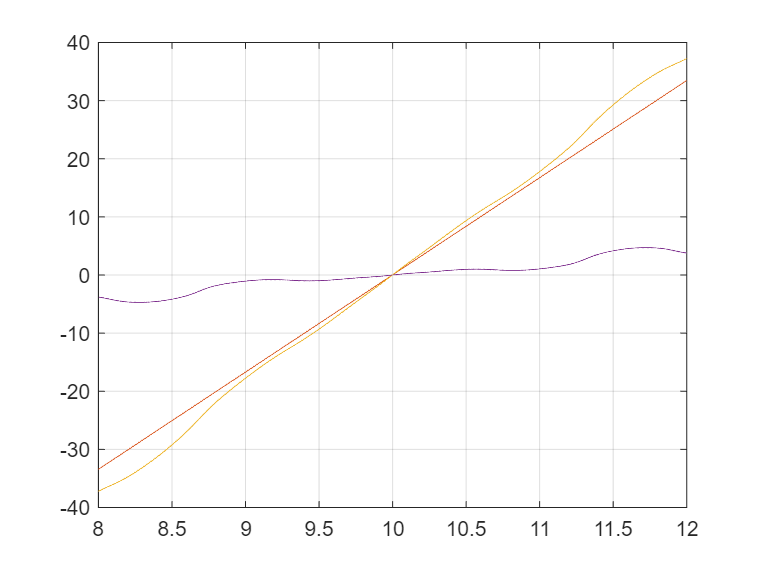

plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
xlim([8 12])
grid on
% plot(zData(unwrapN_1:unwrapNe),phase0(unwrapN_1:unwrapNe));
%最小二乘
coefficient=polyfit(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe),1); 
LSM=polyval(coefficient,zData(unwrapN_1:unwrapNe));
hold on 
plot(zData(unwrapN_1:unwrapNe),LSM);
plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe))
xlim([8 12])
plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe)-LSM);
xlim([8 12])

function [fSigma,sigmai] = fitfSigma(x)
%Coefficients (with 95% confidence bounds):
       a1 =       88.19  ;%(51.68, 124.7)
       b1 =       1.378  ;%(1.347, 1.409)
       c1 =      0.1243  ;%(0.0879, 0.1606)
       a2 =      0.9322  ;%(-1.209, 3.073)
       b2 =       1.542  ;%(1.518, 1.565)
       c2 =     0.01341  ;%(-0.02512, 0.05195)
       a3 =       69.18  ;%(-6.223, 144.6)
       b3 =        1.27  ;%(1.228, 1.312)
       c3 =     0.07202  ;%(0.03205, 0.112)
       a4 =       528.7  ;%(493.5, 563.8)
       b4 =       1.488  ;%(1.483, 1.494)
       c4 =      0.2199  ;%(0.2153, 0.2245)
       a5 =       62.39  ;%(-14.96, 139.7)
       b5 =       1.207  ;%(1.188, 1.225)
       c5 =     0.05735  ;%(0.04772, 0.06698)
       a6 =         181  ;%(163.3, 198.6)
       b6 =        1.87  ;%(1.867, 1.873)
       c6 =       0.158  ;%(0.153, 0.1629)
       a7 =      -60.41  ;%(-80.21, -40.6)
       b7 =        1.92  ;%(1.789, 2.051)
       c7 =      0.4102  ;%(0.3363, 0.4841)
       a8 =       57.07  ;%(54.59, 59.55)
       b8 =       1.735  ;%(1.728, 1.742)
       c8 =       1.039  ;%(1.023, 1.054)
     fSigma = a1*exp(-((x-b1)/c1).^2) + a2*exp(-((x-b2)/c2).^2) +... 
              a3*exp(-((x-b3)/c3).^2) + a4*exp(-((x-b4)/c4).^2) + ...
              a5*exp(-((x-b5)/c5).^2) + a6*exp(-((x-b6)/c6).^2) + ...
              a7*exp(-((x-b7)/c7).^2) + a8*exp(-((x-b8)/c8).^2);
     sigmai = [b1 b2 b3 b4 b5 b6 b7 b8];
end